clear all; close all; clc;

Normal distribution

1A

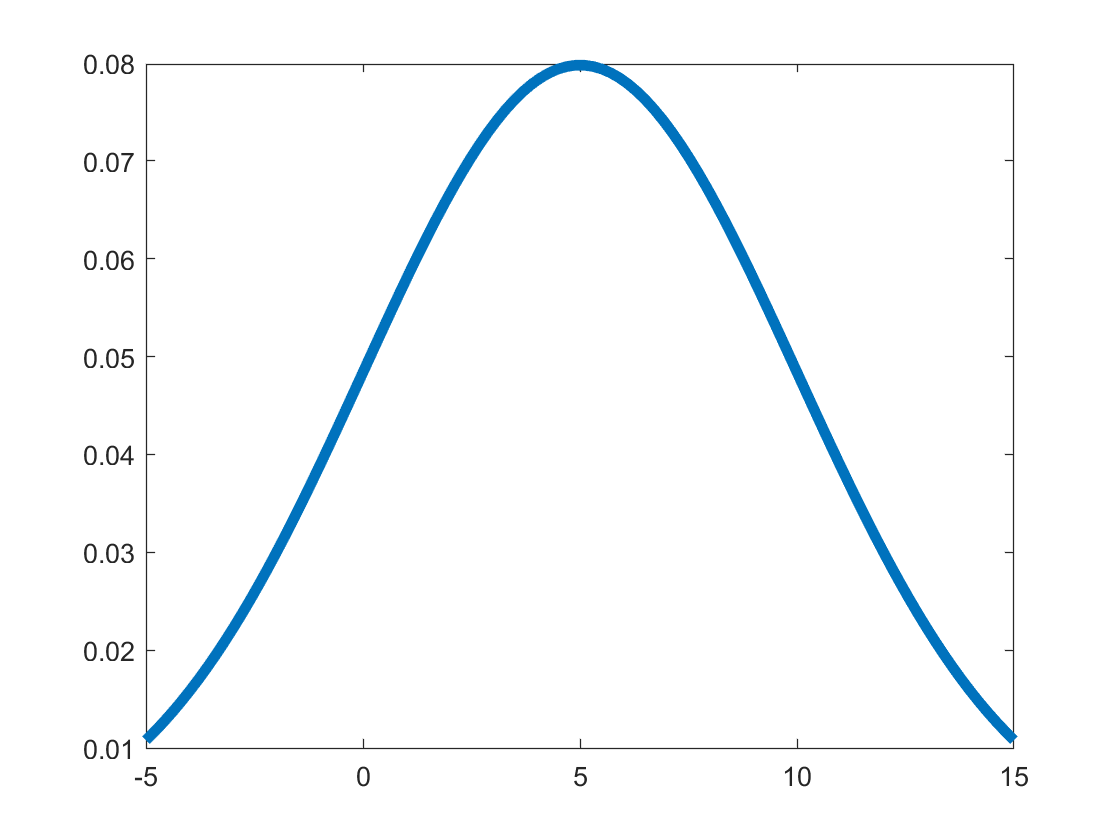


mu = 5;
sigma = 5;
x = linspace(-5,15,100);
probdist= makedist('Normal',"mu",mu,"sigma",sigma);

plot(x, pdf(probdist,x), "LineWidth",4);

1B

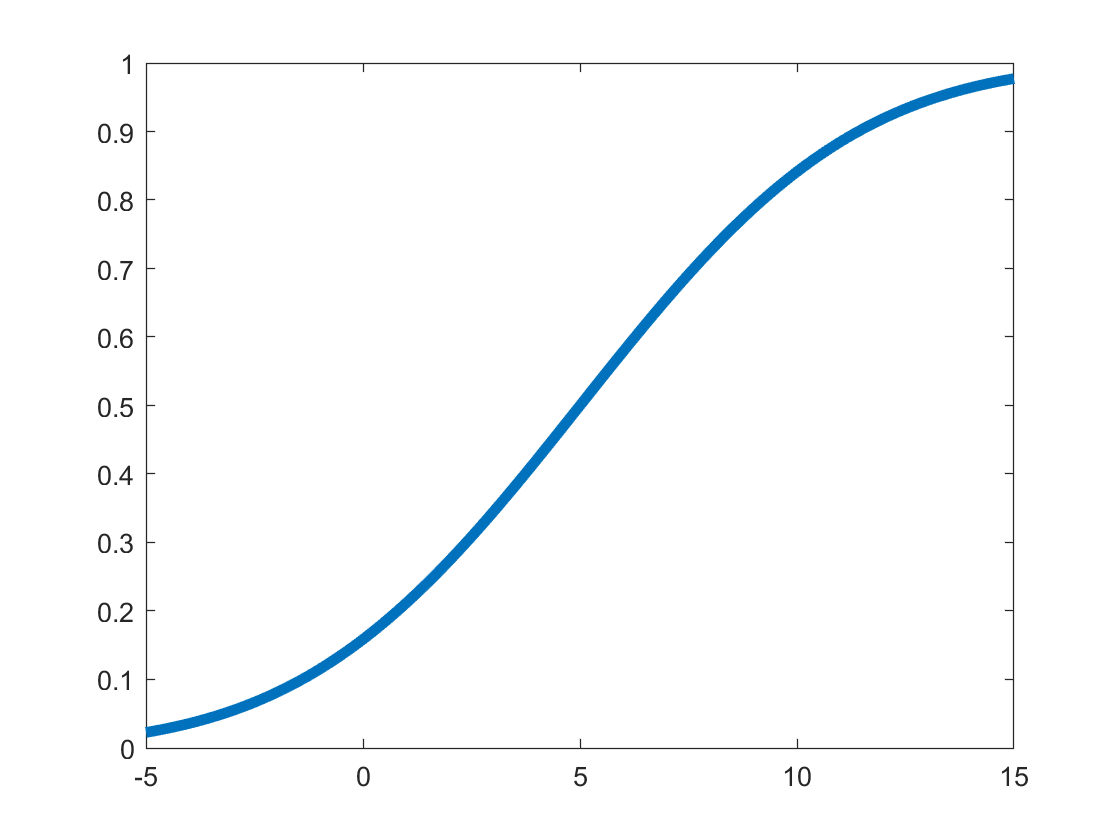

distfunc = normcdf(x,mu,sigma);
plot(x,distfunc,"LineWidth",4);

1C

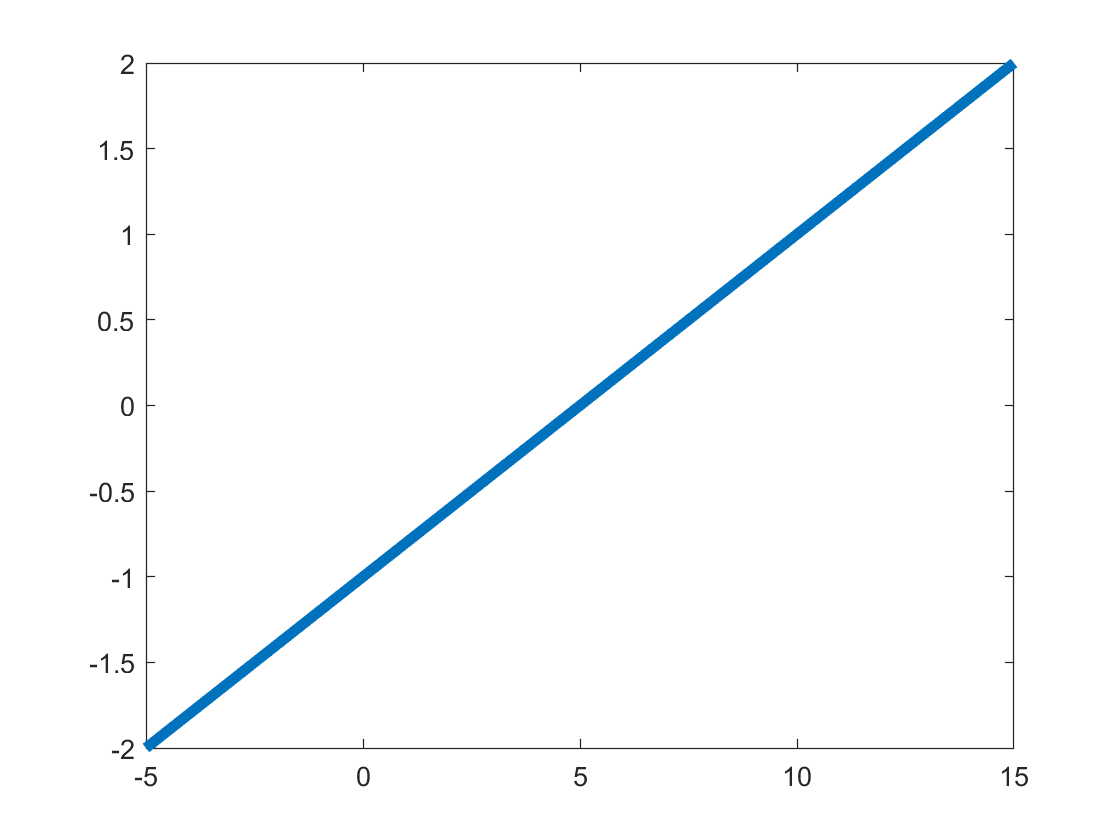

sigmavalues = norminv(distfunc); %gives sigma value for each input
plot(x, sigmavalues,"LineWidth",4);

1D 

negative sigma values make sense because the left side of the graph values are smaller than the mean and sigma is defined as (x-mean)^2

2. I chose Rayleigh distribution

2A The Rayleigh distribution is the distribution for a number of vectors with 2 degrees of freedom.  An example of the distribution arises in the case of random complex numbers whose real and imaginary components are independently and identically distributed Gaussian with equal variance and zero mean. In that case, the absolute value of the complex number is Rayleigh-distributed.

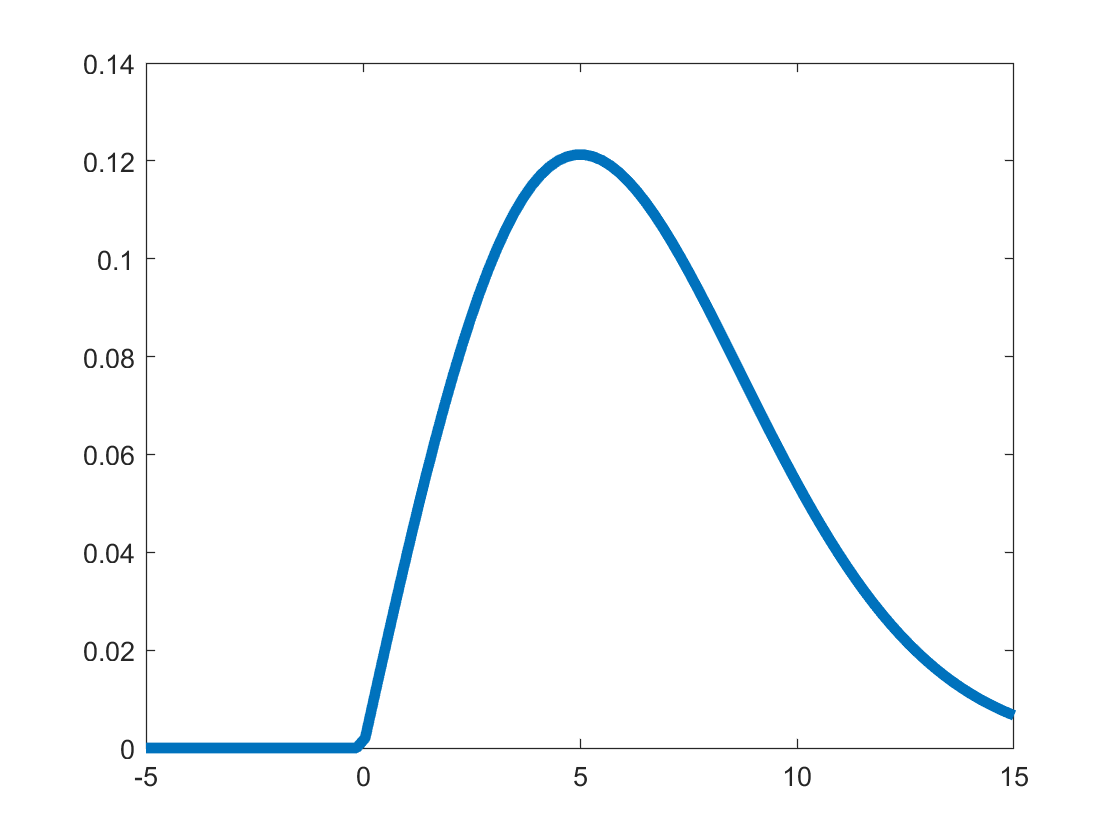

 y = linspace(0,10, 100000);
 b = 5;
 rayl = makedist("Rayleigh",'b',b);
 plot(x,pdf(rayl,x),"LineWidth",4);

2B the b value is the scale parameter of the distribution. The larger b is, the more spread out the distribution is. Also, the value of b is the value of the median.

3. The hypothetical data I have is 100k complex vectors.

3A How many of them have a magnitude less than 5? Is this a valid hypothetical question

3B How different is the signal-free data from the 


$$\int_{0}^{5}{\frac{ x}{b^2}e^{-x^2}sin(x) dx$$


 %some code calculating sigma and if it is within acceptable range

4. Binomial distribution

4A 

N = number of entries

p = location of peak on the distribution of N values (Range 0-1)

4B  I made a list of 40 values of x, and a corresponding pdf

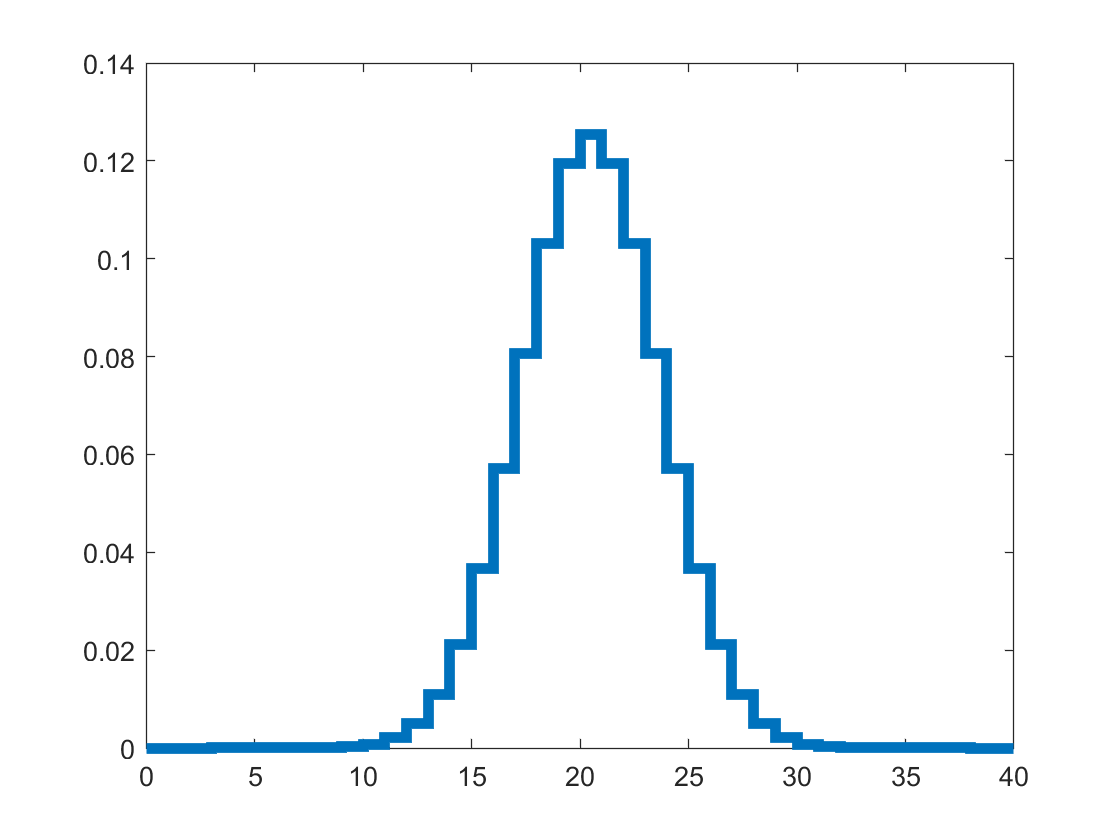

x = 0:40;
bin1 = makedist("Binomial",'N',40, 'p',0.5); 
stairs(x,pdf(bin1,x),"LineWidth",4);

N = 40 is equivalent to the number of values of x, so p = 0.5 is around 20

bin2 = makedist("Binomial",'N',80, 'p',0.5); 

N = 80 is bigger than the number of entries so the p value is around 0.5*80=40 which is where the peak is located

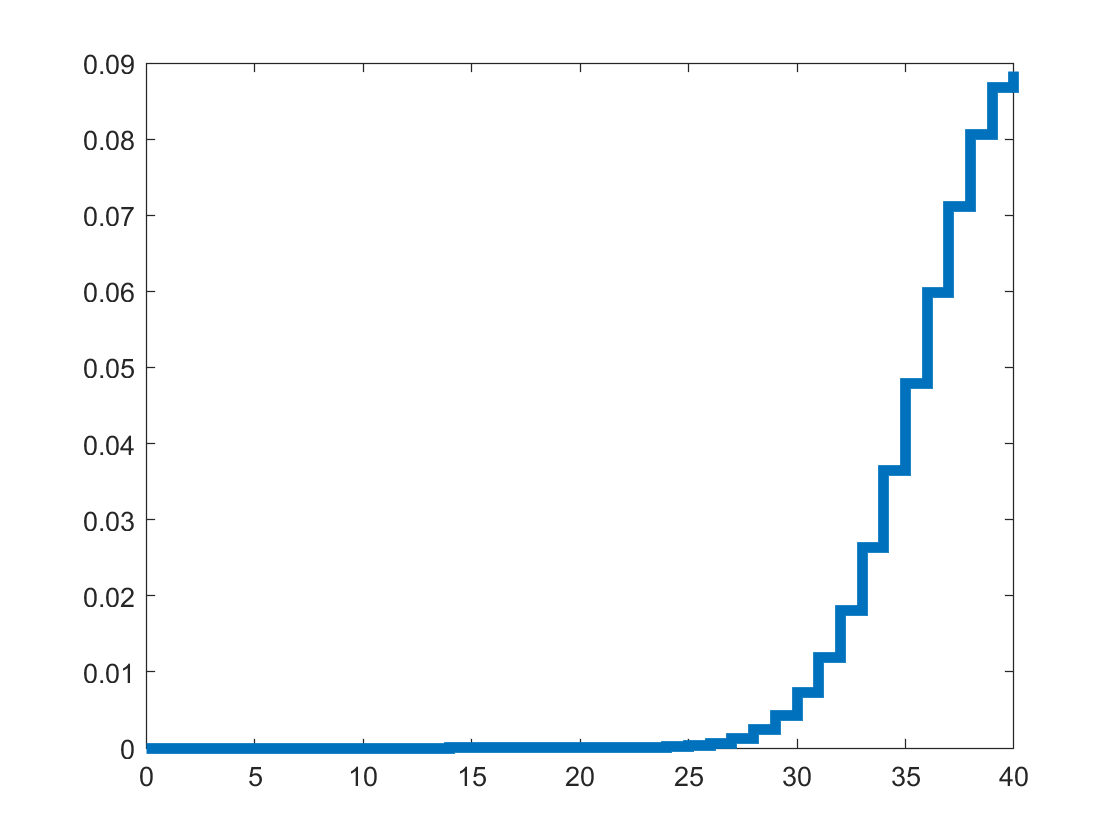

stairs(x,pdf(bin2,x),"LineWidth",4);

bin1 = makedist("Binomial",'N',40, 'p',0.05); 

Location of the peak is 0.05*40=2

4C I am unsure of the type of the hypothetical question once again

4B